#### Escuela Superior de Ingeniería y Tecnología (UNIR)

## Máster Universitario en Ingeniería Matemática y Computación

### - OPTIMIZACIÓN -

# Actividad 1: Optimización de funciones

**Alumno:** Pablo Ruiz Molina

## 1. Selección de intervalo de longitud 1 de las funciones test

En el primer apartado de esta actividad se busca seleccionar un intervalo de longitud 1, en el cual la función sea unimodal y contenga el mínimo localizado en el valor positivo más pequeño.

Para entender qué tipo de funciones hay que enfrentar, el primer paso es visualizarlas. Se han escogido rangos ciertamente amplios para entender las funciones de manera general. El código usado para ello es el siguiente:

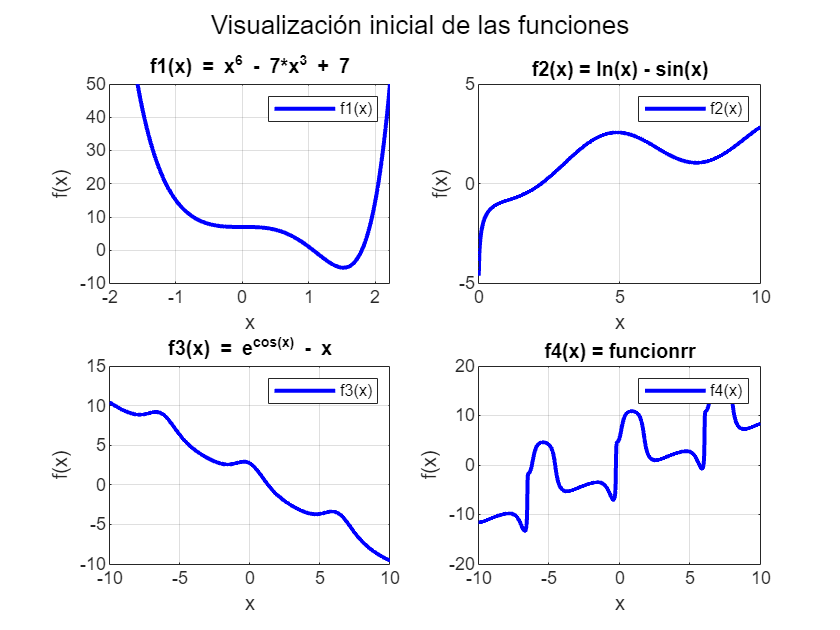

% Visualización inicial de las funciones 

% Limpieza de la consola, variables y figuras
clc; clear; close all;

% Definición de las funciones objetivo
f1 = @(x) (x.^6) - 7*(x.^3) + 7;
f2 = @(x) log(x) - sin(x);
f3 = @(x) exp(1).^cos(x) - x;
f4 = @(x) funcionrr(x);
%f4 = @(x) (x-2).^2;

funciones_id = {'f1(x)'; 'f2(x)'; 'f3(x)'; 'f4(x)'};
f = {f1; f2; f3; f4};

%% Visualización inicial
x1_values = linspace(-10, 10, 1000); y1_values = f1(x1_values);
x2_values = linspace(0, 10, 1000); y2_values = f2(x2_values);
x3_values = linspace(-10, 10, 1000); y3_values = f3(x3_values);
x4_values = linspace(-10, 10, 1000); y4_values = f4(x4_values);

x_values = [x1_values; x2_values; x3_values; x4_values];
y_values = [y1_values; y2_values; y3_values; y4_values];

figure (1)
subtitles = {'f1(x) = x^6 - 7*x^3 + 7';
             'f2(x) = ln(x) - sin(x)';
             'f3(x) = e^{cos(x)} - x';
             'f4(x) = funcionrr'};
ylims = [[-10, 50]; [-5, 5]; [-10, 15]; [-20, 20]];
legends = {'f1(x)'; 'f2(x)'; 'f3(x)'; 'f4(x)'};

for i = 1:4
    subplot(2, 2, i), plot(x_values(i,:), y_values(i,:), 'b-', 'LineWidth', 2);
    title(subtitles{i},'Interpreter', 'tex');
    ylim(ylims(i,:));
    xlabel('x');
    ylabel('f(x)');
    legend(legends{i});
    hold on;
    grid on;
end

sgtitle('Visualización inicial de las funciones');

A destacar cómo la segunda función (arriba a la derecha) cuenta con un límite de $-\infty$ en $x\ =\ 0$. Es de hecho esperable según el rango donde se define la función en el enunciado: $\left(0,\ \infty \right)$.

Es fácil seleccionar para cada función un intervalo unidad en el que la función sea unimodal, con un mínimo, y que a su vez sea el más cercano a 0 por la parte positiva.

%% Selección del intervalo de búsqueda de cada función
intervalo_f = [[1, 2]; [7.25, 8.25]; [4.25, 5.25]; [2, 3]];

xlims = [[0, 3]; [6, 9]; [3.25, 6.25]; [1, 4]];
ylims = [[-20, 30]; [0.5, 2]; [-4.5, -2.5]; [-3, 10]];

% Visualización de los intervalos
figure (2);
for i = 1:4
    subplot(2, 2, i), plot(x_values(i,:), y_values(i,:), 'b-', 'LineWidth', 2);
    subplot(2, 2, i), xline(intervalo_f(i, 1), '--r', 'a', 'LabelOrientation', 'horizontal', 'LineWidth', 1.5);
    subplot(2, 2, i), xline(intervalo_f(i, 2), '--g', 'b', 'LabelOrientation', 'horizontal', 'LineWidth', 1.5);
    title(subtitles{i},'Interpreter', 'tex');
    xlim(xlims(i,:));
    ylim(ylims(i,:));
    xlabel('x');
    ylabel('f(x)');
    legend(legends{i});
    hold on;
    grid on;
end

sgtitle('Selección de intervalos');

## 2. Métodos de búsqueda

Una vez los intervalos de búsqueda están seleccionados, se van a desarrollar y probar los diferentes métodos de búsqueda objetivo de la actividad.

### 2.1 Método de búsqueda dicotómica

La búsqueda dicotómica es un método simple y eficiente diseñado para encontrar el mínimo de una función unimodal dentro de un intervalo dado. Este tipo de función tiene una sola tendencia descendente seguida de una ascendente (o viceversa), garantizando que exista un único mínimo local dentro del intervalo considerado. El algoritmo es iterativo y trabaja reduciendo progresivamente el tamaño del intervalo donde se encuentra el mínimo, basándose en evaluaciones estratégicas de la función en puntos seleccionados dentro del intervalo. El código implementado ha sido el siguiente:

function [x_min, iter] = budi(f, a, b, delta)
    % Método de búsqueda dicotómica
    % Entradas:
    %   f: función objetivo
    %   a, b: extremos iniciales del intervalo unimodal
    %   delta: tolerancia para la convergencia
    %
    % Salidas:
    %   x_min: punto donde se alcanza el mínimo
    %   iter: número de iteraciones realizadas

    % Implementación del método

    % valores iniciales
    eps = delta/10; % Siempre más pequeño que la tolerancia.
    % Distancia entre los puntos (epsilon < delta)

    % Inicialización de las variables
    iter = 0;  % Contador de iteraciones
    max_iter = 100;  % Número máximo de iteraciones
    
    % mientras (b - a) >= tol
    while (b - a) > delta && iter < max_iter
        iter = iter + 1;

        % Calcular xa y xb
        x = (a + b)/2; 
        xa = x - eps/2;
        xb = x + eps/2;

        % Evaluar la función en los extremos del nuevo intervalo
        if f(xa) < f(xb)
            b = xb;
        else
            a = xa;
        end
    end
    % Cálculo del mínimo
    x_min = (a + b) / 2;
end

En este algoritmo de búsqueda se puede destacar cómo hay que evaluar la función en cada extremo del intervalo (2 veces por iteración).  Los resultados obtenidos una vez se pasa el algoritmo a todas las funciones son los siguientes:

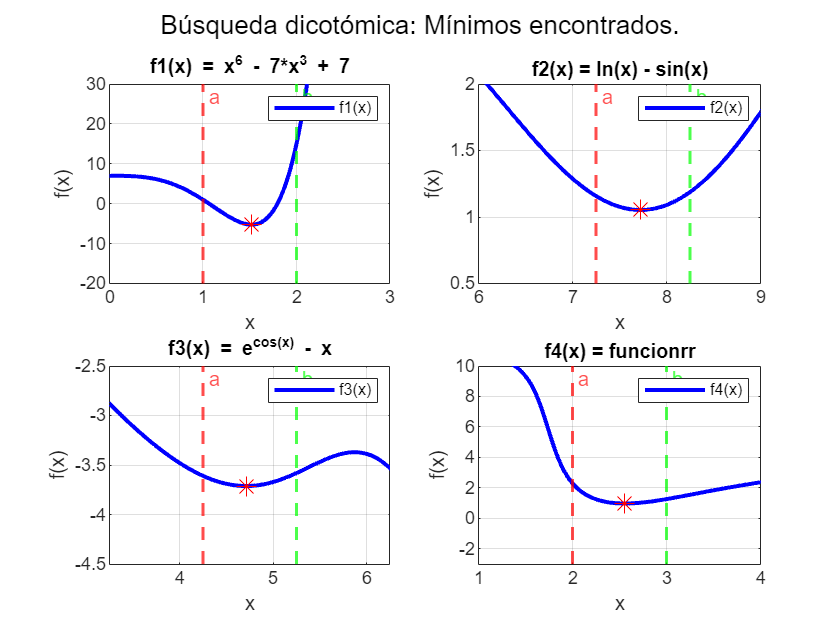

% Parámetros de la interpolación cuadrática
delta = 1e-6;  % Tolerancia (delta)

% Ejecución del método para cada función
x_min_budi = zeros(1, 4); 
iter_budi = zeros(1, 4);
tiempos_budi = zeros(1, 4);
f_min_budi = zeros(1, 4);
for i = 1:4
    tic;
    [x_min_budi(i), iter_budi(i)] = budi(f{i}, intervalo_f(i, 1), intervalo_f(i, 2), delta);
    tiempos_budi(i) = toc * 1000;
    f_min_budi(i) = f{i}(x_min_budi(i));
end

% Representación de los resultados para cada función
figure (4)
titulo_budi = 'Búsqueda dicotómica: Mínimos encontrados.';
plot_minimos(x_values, y_values, intervalo_f, xlims, ylims, x_min_budi, f_min_budi, subtitles, legends, titulo_budi)

Se aprecia a simple vista cómo se encuentra el punto mínimo en cada una de las funciones de manera precisa.

En la siguiente tabla, se detallan los valores obtenidos para el valor x_min, para el valor que cobra la función, las iteraciones necesarias, así como el tiempo de ejecución:

% Tabla comparativa
T_budi = table(funciones_id, x_min_budi', f_min_budi', iter_budi', tiempos_budi', 'VariableNames', {'Funciones', 'x min', 'f(x min)', 'Iteraciones', 'Tiempos (msec)'});
disp(T_budi);

    Funciones    x min     f(x min)    Iteraciones    Tiempos (msec)
    _________    ______    ________    ___________    ______________

    {'f1(x)'}    1.5183      -5.25         21              1.116    
    {'f2(x)'}    7.7242     1.0528         21             1.1811    
    {'f3(x)'}    4.7124    -3.7124         21              0.382    
    {'f4(x)'}    2.5574    0.97258         21             195.41    



Será interesante comparar a continuación con los siguientes métodos los resultados de los valores x mínimos y los valores que toma la función en esos mínimos. 

En relación con las iteraciones, es interesante darse cuenta cómo para todas las funciones se consume el mismo número de ellas, 21 en este caso. Podemos calcular las iteraciones mínimas necesarias por este algoritmo, en base a la tolerancia escogida:

% Cálculo de las iteraciones mínimas de Budi
iter_min_budi = log(delta)/log(.5);
disp(['Número de iteraciones mínimas para búsqueda dicotómica: iter_min <= ', num2str(ceil(iter_min_budi))])

Número de iteraciones mínimas para búsqueda dicotómica: iter_min <= 20


Se aprecia cómo de acuerdo al parámetro delta escogido, son 20 iteraciones como mínimo. Como se comentaba, en los 4 casos se han usado 21 iteraciones, lo cuál como mínimo entra dentro de lo esperado.

En cuanto al tiempo de ejecución, se observa cómo para las tres primeras funciones el valor ronda entre 0.5-1.5 milisegundos. Mientras que para la función 4, el tiempo se dispara hasta casi los 200 milisegundos. Esto se debe a que las evaluciones que necesita hacer la función son en esta última función mucho más costosas por ser una función numérica un tanto compleja.

### 2.2 Método de interpolación cuadrática (*incu.m*)

La interpolación cuadrática es un método iterativo y eficiente para encontrar el mínimo de una función suave dentro de un intervalo dado. Este método asume que la función puede ser aproximada localmente por una parábola, y utiliza tres puntos del intervalo para construir esta aproximación cuadrática. A partir de esta parábola, se estima el punto donde ocurre el mínimo, lo que permite ajustar el intervalo para acercarse progresivamente al mínimo real. El proceso se repite iterativamente hasta alcanzar una precisión deseada, refinando el intervalo en cada paso y mejorando la aproximación del mínimo. El código implementado ha sido el siguiente:

function [x_min, iter] = incu(f, x1, x2, x3, delta)
    % Método de interpolación cuadrática
    % Entradas:
    %   f: función objetivo
    %   x1, x2, x3: puntos iniciales en los que x2<x1 y x2<3
    %   delta: tolerancia para la convergencia
    %
    % Salidas:
    %   x_min: punto donde se alcanza el mínimo
    %   iter: número de iteraciones realizadas

    % Implementación del método
    % Inicialización de las variables
    iter = 0;  % Contador de iteraciones
    max_iter = 100;  % Número máximo de iteraciones
    
    while iter < max_iter 
        iter = iter + 1;

        % Calcular el valor mínimo del polinomio interpolador
        f1 = f(x1); f2 = f(x2); f3 = f(x3);
        num = ((x2^2-x3^2)*f1 + (x3^2-x1^2)*f2 + (x1^2-x2^2)*f3);
        den = 2*((x3-x2)*f1 + (x1-x3)*f2 + (x2-x1)*f3);
        x = -num/den;
        
        % Se cumple el criterio de parada?
        if abs(x2 - x) < delta
            x_min = x;
            return
        else
            % Se reduce el intervalo
            if x2 <= x
                x1 = x2; x2 = x; 
            else
                x3 = x2; x2 = x;
            end
        end
    end
    x_min = 0;

end

En este caso, lo más destacable es el cálculo del mínimo del polinomio interpolador. También es interesante notar cómo en cada iteración se necesita evaluar la función 3 veces. Esto es una vez más que en el método de la búsqueda dicotómica, lo que a priori lo pondría en desventaja. Como se verá a continuación, la parte positiva es que requiere menos iteraciones para obtener el mínimo. Los resultados obtenidos una vez se pasa el algoritmo a todas las funciones son los siguientes:

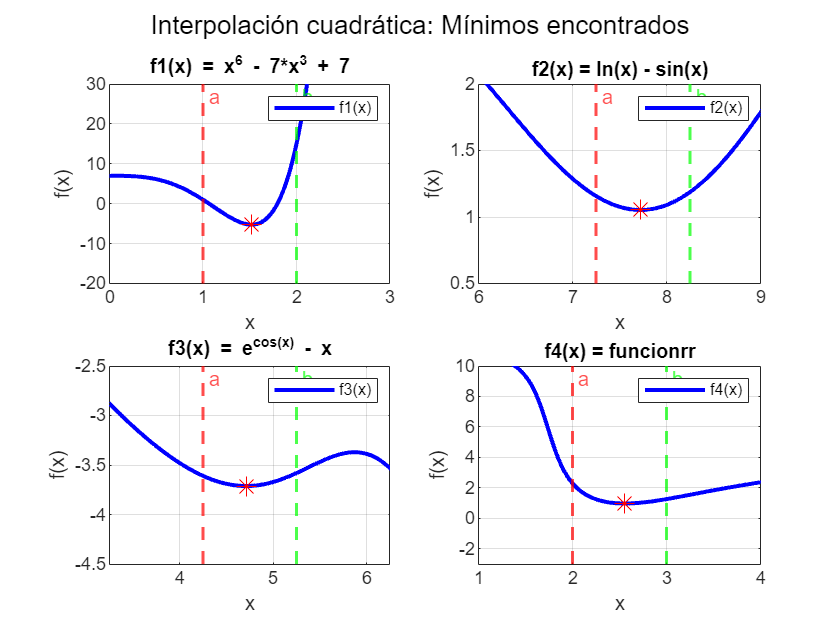

% Parámetros de la interpolación cuadrática
delta = 1e-6;  % Tolerancia (delta)

% Ejecución del método para cada función
x_min_incu = zeros(1, 4); 
iter_incu = zeros(1, 4);
tiempos_incu = zeros(1, 4);
f_min_incu = zeros(1, 4);
for i = 1:4
    tic;
    [x_min_incu(i), iter_incu(i)] = incu(f{i}, intervalo_f(i, 1), (intervalo_f(i, 1) + intervalo_f(i, 2))/2, intervalo_f(i, 2), delta);
    tiempos_incu(i) = toc * 1000;
    f_min_incu(i) = f{i}(x_min_incu(i));
end

% Representación de los resultados para cada función
figure (5)
titulo_incu = 'Interpolación cuadrática: Mínimos encontrados';
plot_minimos(x_values, y_values, intervalo_f, xlims, ylims, x_min_incu, f_min_incu, subtitles, legends, titulo_incu)

Se aprecia a simple vista cómo se encuentra el punto mínimo en cada una de las funciones de manera precisa.

En la siguiente tabla, se detallan los valores obtenidos para el valor x_min, para el valor que cobra la función, las iteraciones necesarias, así como el tiempo de ejecución:

% Tabla comparativa
T_incu = table(funciones_id, x_min_incu', f_min_incu', iter_incu', tiempos_incu', 'VariableNames', {'Funciones', 'x min', 'f(x min)', 'Iteraciones', 'Tiempos (msec)'});
disp(T_incu);

    Funciones    x min     f(x min)    Iteraciones    Tiempos (msec)
    _________    ______    ________    ___________    ______________

    {'f1(x)'}    1.5183      -5.25          9             1.6768    
    {'f2(x)'}    7.7242     1.0528          5             1.3938    
    {'f3(x)'}    4.7124    -3.7124          5             0.6753    
    {'f4(x)'}    2.5574    0.97258          7             99.352    



Ya se puede comprobar cómo los valores mínimos obtenidos coinciden con el método de búsqueda dicotómica. Al final de la Actividad se presenta una tabla comparativa entre todos ellos.

En relación con las iteraciones, es interesante notar como ahora hay dos funciones que ocupan 5 iteraciones mientras la función 4 ocupa 7 y la función 1 ocupa 9. De manera intuitiva se puede identificar que en aquellas funciones donde el mínimo tiene menos pendiente, se hace más complicado para el método cerrar el intervalo y por tanto tarda más iteraciones.

En cuanto al tiempo de ejecución, se observa cómo para las tres primeras funciones el valor ronda entre 1-2 milisegundos. Mientras que para la función 4, el tiempo se dispara hasta casi los 100 milisegundos. Esto se debe de nuevo a que las evaluciones que necesita hacer la función son en esta última función mucho más costosas por ser una función numérica un tanto compleja.

### 2.3 Método de Newton (new*.m*)

El método de Newton es un método iterativo y eficiente para encontrar el mínimo de una función suave utilizando información de su derivada y derivada segunda. Este método asume que la función puede aproximarse localmente mediante una parábola utilizando una expansión en serie de Taylor de segundo orden. En cada iteración, calcula el punto donde la derivada de la parábola se anula, estimando así el próximo valor del mínimo. Este nuevo punto se convierte en la base para la siguiente iteración, refinando progresivamente la aproximación al mínimo real. El proceso continúa hasta que se alcanza una precisión deseada, dependiendo de la convergencia rápida garantizada por la naturaleza cuadrática del método en funciones suficientemente suaves. A continuación se adjunta el código empleado:

function [x_min, iter] = new(f, intervalo, delta)
    % Método de Newton
    % Entradas:
    %   f: función objetivo
    %   intervalo: intervalo objetivo
    %   delta: tolerancia para la convergencia
    %
    % Salidas:
    %   x_min: punto donde se alcanza el mínimo
    %   iter: número de iteraciones realizadas

    % Implementación del método

    % valores iniciales
    iter = 0;
    max_iter = 100;  % Número máximo de iteraciones
    error1 = delta + 1;
    error2 = delta + 1;
    h = 1/1000; % Cada función está muestreada con 1000 muestras.
    x_n = intervalo(1) + (intervalo(2) - intervalo(1))/2; % x inicial = Punto medio del intervalo

    while (error1 > delta || error2 > delta) && iter < max_iter
        iter = iter + 1;

        % Se evaluan las derivadas usando aproximación de diferencias
        % finitas centrales
        fx_2h = f(x_n + 2*h);
        fx_h = f(x_n + h);
        fx_nh = f(x_n - h);
        fx_2nh = f(x_n - 2*h);
        
        %f_p= -f(x+2h) + 8*f(x+h) - 8*f(x-h) + f(x-2h)/12h
        f_p = (-fx_2h + 8*fx_h - 8*fx_nh + fx_2nh)/(12*h);
        %f_pp= -f(x+2h) + 16*f(x+h) - 30*f(x) + 16f(x-h) - f(x-2h)/12h^2
        f_pp = (-fx_2h + 16*fx_h - 30*f(x_n) + 16*fx_nh - fx_2nh)/(12*(h^2));

        % Se actualiza el valor de x_n + 1
        x_n_1 = x_n - f_p/f_pp;

        % Se evaluan los errores
        error1 = abs(x_n_1 - x_n);
        f_p = (-f(x_n_1 + 2*h) + 8*f(x_n_1 + h) - 8*f(x_n_1 - h) + f(x_n_1 - 2*h))/(12*h);
        error2 = abs(f_p);
        
        % Se actualiza x_n, que será el mínimo si no hay más iteraciones
        x_n = x_n_1;
        x_min = x_n;
    end
end

De este código hay que comentar que se ha usado la aproximación en diferencias finitas central para calcular tanto la primera derivada como la segunda. Esto es así dado que la función 4 no permitía calcular las derivadas mediante expresiones simbólicas. Por otro lado, cabe comentar que en cada iteración hay que hacer al menos 8 evaluaciones de la función, 4 sobre el valor x_n para las aproximaciones de f_p y f_pp, y otras 4 para aproximar f_p sobre x_n + 1. Esto puede compensar, no obstante, el hecho de que converga más rápido que los dos métodos anteriores. A continación se muestran los resultados:

% Parámetros del método de Newton
delta = 1e-6;  % Tolerancia (delta)

% Ejecución del método para cada función
x_min_new = zeros(1, 4); 
iter_new = zeros(1, 4);
tiempos_new = zeros(1, 4);
f_min_new = zeros(1, 4);

for i = 1:4
    tic;
    [x_min_new(i), iter_new(i)] = new(f{i}, intervalo_f(i,:), delta); 
    tiempos_new(i) = toc * 1000;
    f_min_new(i) = f{i}(x_min_new(i));
end

% Representación de los resultados para cada función
figure (6)
titulo_new = 'Método de Newton: Mínimos encontrados';
plot_minimos(x_values, y_values, intervalo_f, xlims, ylims, x_min_new, f_min_new, subtitles, legends, titulo_new)

En la siguiente tabla, se detallan los valores obtenidos para el valor x_min, para el valor que cobra la función, las iteraciones necesarias, así como el tiempo de ejecución:

% Tabla comparativa
T_new = table(funciones_id, x_min_new', f_min_new', iter_new', tiempos_new', 'VariableNames', {'Funciones', 'x min', 'f(x min)', 'Iteraciones', 'Tiempos (msec)'});
disp(T_new);

    Funciones    x min     f(x min)    Iteraciones    Tiempos (msec)
    _________    ______    ________    ___________    ______________

    {'f1(x)'}    1.5183      -5.25          3             1.0202    
    {'f2(x)'}    7.7242     1.0528          3             2.3137    
    {'f3(x)'}    4.7124    -3.7124          3             1.1679    
    {'f4(x)'}    2.5574    0.97258          4             165.62    



Se aprecia como los mínimos vuelven a ser correctos. En cuanto a las iteraciones, en este caso, el método se toma menos que los dos anteriores, por lo que se considera más eficiente. Los  tiempos sin embargo no son excelentes, debido en gran parte a la gran cantidad de evaluaciones que requiere hacer sobre la función para aproximar la derivada. No obstante, este tiempo se podría reducir si se usara un orden menor para dicha aproximación.

### 2.4 Método de las rectas inexactas (rein*.m*)

El método de las rectas inexactas es un procedimiento iterativo utilizado para encontrar el mínimo de una función suave a lo largo de una dirección determinada. Este método evalúa la función en dos puntos de prueba dentro de un intervalo inicial, seleccionando la dirección en la que la función decrece más rápidamente. Posteriormente, ajusta el intervalo de búsqueda en cada iteración, basándose en condiciones específicas (como las condiciones de Armijo o Wolfe) que aseguran un descenso suficiente y una convergencia estable. El proceso se repite iterativamente, refinando la estimación del mínimo hasta alcanzar un nivel de precisión deseado. A continuación se adjunta el código empleado:

function [x_min, iter] = new1(f, intervalo, delta)
    % Método de Newton
    % Entradas:
    %   f: función objetivo
    %   intervalo: intervalo objetivo
    %   delta: tolerancia para la convergencia
    %
    % Salidas:
    %   x_min: punto donde se alcanza el mínimo
    %   iter: número de iteraciones realizadas

    % Implementación del método

    % valores iniciales
    iter = 0;
    max_iter = 100;  % Número máximo de iteraciones
    error1 = delta + 1;
    error2 = delta + 1;
    h = 1/1000; % Cada función está muestreada con 1000 muestras.
    x_n = intervalo(1) + (intervalo(2) - intervalo(1))/2; % x inicial = Punto medio del intervalo

    while (error1 > delta || error2 > delta) && iter < max_iter
        iter = iter + 1;

        % Se evaluan las derivadas usando aproximación de diferencias
        % finitas centrales
        fx_2h = f(x_n + 2*h);
        fx_h = f(x_n + h);
        fx_nh = f(x_n - h);
        fx_2nh = f(x_n - 2*h);
        
        %f_p= -f(x+2h) + 8*f(x+h) - 8*f(x-h) + f(x-2h)/12h
        f_p = (-fx_2h + 8*fx_h - 8*fx_nh + fx_2nh)/(12*h);
        %f_pp= -f(x+2h) + 16*f(x+h) - 30*f(x) + 16f(x-h) - f(x-2h)/12h^2
        f_pp = (-fx_2h + 16*fx_h - 30*f(x_n) + 16*fx_nh - fx_2nh)/(12*(h^2));

        % Se actualiza el valor de x_n + 1
        x_n_1 = x_n - f_p/f_pp;

        % Se evaluan los errores
        error1 = abs(x_n_1 - x_n);
        f_p = (-f(x_n_1 + 2*h) + 8*f(x_n_1 + h) - 8*f(x_n_1 - h) + f(x_n_1 - 2*h))/(12*h);
        error2 = abs(f_p);
        
        % Se actualiza x_n, que será el mínimo si no hay más iteraciones
        x_n = x_n_1;
        x_min = x_n;
    end
end

De este código hay que comentar que se ha usado la aproximación en diferencias finitas central para calcular tanto la primera derivada como la segunda. Esto es así dado que la función 4 no permitía calcular las derivadas mediante expresiones simbólicas. Por otro lado, cabe comentar que en cada iteración hay que hacer al menos 8 evaluaciones de la función, 4 sobre el valor x_n para las aproximaciones de f_p y f_pp, y otras 4 para aproximar f_p sobre x_n + 1. Esto puede compensar, no obstante, el hecho de que converga más rápido que los dos métodos anteriores. A continación se muestran los resultados:

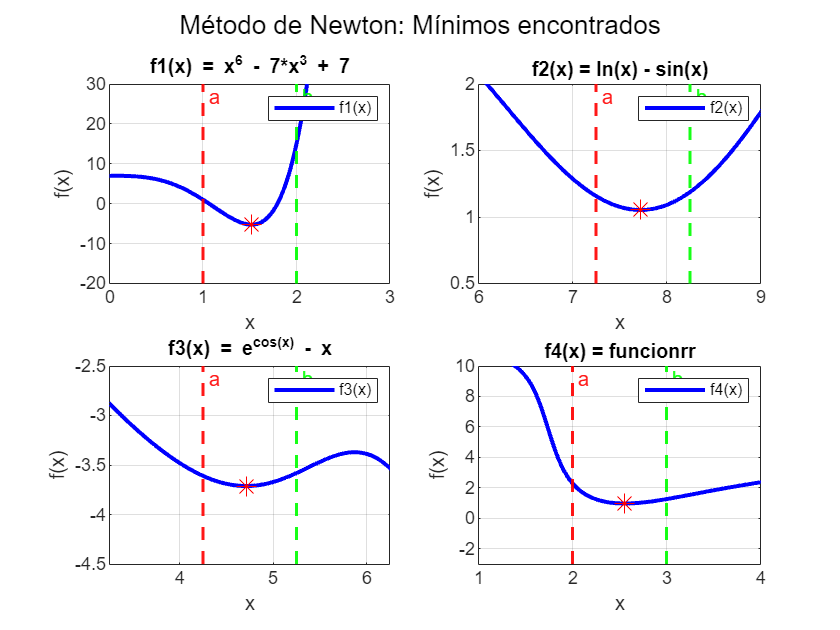

% Parámetros del método de Newton
delta = 1e-6;  % Tolerancia (delta)

% Ejecución del método para cada función
x_min_new = zeros(1, 4); 
iter_new = zeros(1, 4);
tiempos_new = zeros(1, 4);
f_min_new = zeros(1, 4);

for i = 1:4
    tic;
    [x_min_new(i), iter_new(i)] = new(f{i}, intervalo_f(i,:), delta); 
    tiempos_new(i) = toc * 1000;
    f_min_new(i) = f{i}(x_min_new(i));
end

% Representación de los resultados para cada función
figure (6)
titulo_new = 'Método de Newton: Mínimos encontrados';
plot_minimos(x_values, y_values, intervalo_f, xlims, ylims, x_min_new, f_min_new, subtitles, legends, titulo_new)

En la siguiente tabla, se detallan los valores obtenidos para el valor x_min, para el valor que cobra la función, las iteraciones necesarias, así como el tiempo de ejecución:

% Tabla comparativa
T_new = table(funciones_id, x_min_new', f_min_new', iter_new', tiempos_new', 'VariableNames', {'Funciones', 'x min', 'f(x min)', 'Iteraciones', 'Tiempos (msec)'});
disp(T_new);

    Funciones    x min     f(x min)    Iteraciones    Tiempos (msec)
    _________    ______    ________    ___________    ______________

    {'f1(x)'}    1.5183      -5.25          3              0.628    
    {'f2(x)'}    7.7242     1.0528          3             0.5698    
    {'f3(x)'}    4.7124    -3.7124          3             0.0458    
    {'f4(x)'}    2.5574    0.97258          4             163.36    



Se aprecia como los mínimos vuelven a ser correctos. En cuanto a las iteraciones, en este caso, el método se toma menos que los dos anteriores, por lo que se considera más eficiente. Los  tiempos sin embargo no son excelentes, debido en gran parte a la gran cantidad de evaluaciones que requiere hacer sobre la función para aproximar la derivada. No obstante, este tiempo se podría reducir si se usara un orden menor para dicha aproximación.

## X. Anexo. 

### X.1 Función numérica

La función numérica se ha modificado ligeramente para poder ser llamada como las demás...

function f = funcionrr(x_vec)
    % Inicializa un vector de salida
    f = zeros(size(x_vec));
    
    % Recorre cada valor del vector de entrada
    for i = 1:length(x_vec)
        x = x_vec(i); % Toma el valor actual
        xini=[x 0];
        t=[0 2*pi];
    
        options = odeset('RelTol',1e-13,'AbsTol',1e-13);
    
        [~, xs] = ode45(@campo_pendulo, t, xini, options);
    
        f(i)=xs(end,1);
    end

end

function px = campo_pendulo(t,x)
    px(1) = x(2);
    px(2) = sin(x(1)) + 0.5*sin(t);
    px = px';
end

### X.2 Representación de las gráficas de los mínimos.

function plot_minimos(x_values, y_values, intervalo_f, xlims, ylims, x1_min, f1_min, subtitles, legends, titulo)
    for i = 1:4
            subplot(2, 2, i), plot(x_values(i,:), y_values(i,:), 'b-', 'LineWidth', 2);
            hold on;
            subplot(2, 2, i), xline(intervalo_f(i, 1), '--r', 'a', 'LabelOrientation', 'horizontal', 'LineWidth', 1.5);
            subplot(2, 2, i), xline(intervalo_f(i, 2), '--g', 'b', 'LabelOrientation', 'horizontal', 'LineWidth', 1.5);
            subplot(2, 2, i), plot(x1_min(i), f1_min(i), 'r*', 'MarkerSize', 10, 'MarkerFaceColor', 'r'); 
    
            title(subtitles{i},'Interpreter', 'tex');
            xlim(xlims(i,:));
            ylim(ylims(i,:));
            xlabel('x');
            ylabel('f(x)');
            legend(legends{i});
            hold on;
            grid on;
    end
    sgtitle(titulo);
end